### InitSol

- Wykresy poprawy

- Histogramy

- Tabela zestawieniowa

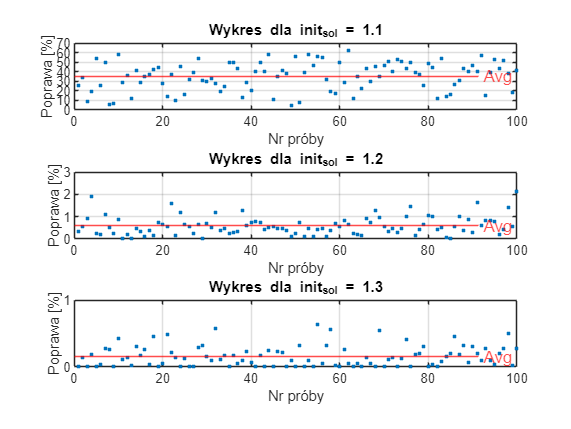

clear all; %#ok<CLALL>
load("results.mat")

init_sol_1_1_rel_imp = initSolData(initSolData.ExperimentName == 1.1, {'RelativeImprovement'});
init_sol_1_2_rel_imp = initSolData(initSolData.ExperimentName == 1.2, {'RelativeImprovement'});
init_sol_1_3_rel_imp = initSolData(initSolData.ExperimentName == 1.3, {'RelativeImprovement'});

init_sol_1_1_rel_imp.RelativeImprovement = init_sol_1_1_rel_imp.RelativeImprovement * 100;
init_sol_1_2_rel_imp.RelativeImprovement = init_sol_1_2_rel_imp.RelativeImprovement * 100;
init_sol_1_3_rel_imp.RelativeImprovement = init_sol_1_3_rel_imp.RelativeImprovement * 100;


init_sol_1_1_rel_imp_avg = mean(init_sol_1_1_rel_imp.RelativeImprovement);
init_sol_1_2_rel_imp_avg = mean(init_sol_1_2_rel_imp.RelativeImprovement);
init_sol_1_3_rel_imp_avg = mean(init_sol_1_3_rel_imp.RelativeImprovement);

init_sol_1_1_rel_imp_std = std(init_sol_1_1_rel_imp.RelativeImprovement);
init_sol_1_2_rel_imp_std = std(init_sol_1_2_rel_imp.RelativeImprovement);
init_sol_1_3_rel_imp_std = std(init_sol_1_3_rel_imp.RelativeImprovement);

init_sol_names = [string(1.1); string(1.2); string(1.3);];
init_sol_avgs = [init_sol_1_1_rel_imp_avg; init_sol_1_2_rel_imp_avg; init_sol_1_3_rel_imp_avg];
init_sol_stds = [init_sol_1_1_rel_imp_std; init_sol_1_2_rel_imp_std; init_sol_1_3_rel_imp_std];

init_sol_comparison = table(init_sol_names, init_sol_avgs, init_sol_stds, 'VariableNames', {'init_sol', 'avg', 'std'});

max_value = max([max(init_sol_1_1_rel_imp.RelativeImprovement), ...
    max(init_sol_1_2_rel_imp.RelativeImprovement), ...
    max(init_sol_1_3_rel_imp.RelativeImprovement)]);
y_axis_limit_plot = ceil(max_value / 10) * 10;

bin_width = 5;
max_count_100 = max(histcounts(init_sol_1_1_rel_imp.RelativeImprovement, 'BinWidth', bin_width));
max_count_1000 = max(histcounts(init_sol_1_2_rel_imp.RelativeImprovement, 'BinWidth', bin_width));
max_count_2000 = max(histcounts(init_sol_1_3_rel_imp.RelativeImprovement, 'BinWidth', bin_width));
y_axis_limit_hist = max([max_count_100, max_count_1000, max_count_2000]) + 10;

figure;

subplot(3, 1, 1);
plot(init_sol_1_1_rel_imp.RelativeImprovement, '.');
yline(init_sol_1_1_rel_imp_avg, 'Color', 'red', 'LineStyle', '-', 'Label', 'Avg', 'LabelVerticalAlignment', 'middle');
title('Wykres dla init_sol = 1.1');
xlabel('Nr próby');
ylabel('Poprawa [%]');
grid on;
ylim([0, y_axis_limit_plot]);
yticks(0:10:y_axis_limit_plot);

subplot(3, 1, 2);
plot(init_sol_1_2_rel_imp.RelativeImprovement, '.');
yline(init_sol_1_2_rel_imp_avg, 'Color', 'red', 'LineStyle', '-', 'Label', 'Avg', 'LabelVerticalAlignment', 'middle');
title('Wykres dla init_sol = 1.2');
xlabel('Nr próby');
ylabel('Poprawa [%]');
grid on;
ylim([0, 3]);
yticks(0:1:y_axis_limit_plot);

subplot(3, 1, 3);
plot(init_sol_1_3_rel_imp.RelativeImprovement, '.');
yline(init_sol_1_3_rel_imp_avg, 'Color', 'red', 'LineStyle', '-', 'Label', 'Avg', 'LabelVerticalAlignment', 'middle');
title('Wykres dla init_sol = 1.3');
xlabel('Nr próby');
ylabel('Poprawa [%]');
grid on;
ylim([0, 1]);
yticks(0:1:y_axis_limit_plot);

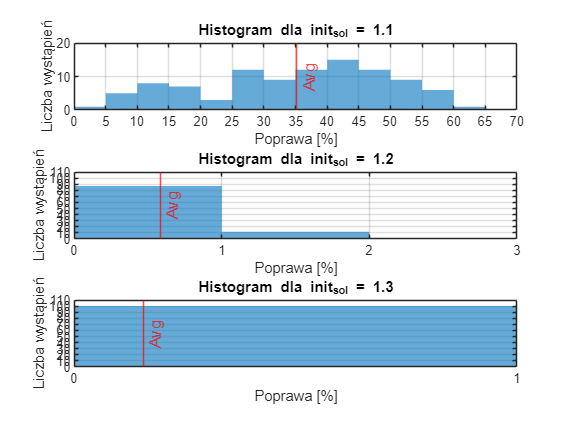


figure;

% Histogram dla init_sol_1_1_rel_imp
subplot(3, 1, 1);
histogram(init_sol_1_1_rel_imp.RelativeImprovement, 'EdgeColor', 'none', 'BinWidth', bin_width);
hold on;
xline(init_sol_1_1_rel_imp_avg, 'Color', 'red', 'LineStyle', '-', 'Label', 'Avg', 'LabelVerticalAlignment', 'middle');
hold off;
title('Histogram dla init_sol = 1.1');
xlabel('Poprawa [%]');
ylabel('Liczba wystąpień');
grid on;
ylim([0, 20]);
xlim([0, y_axis_limit_plot]);
yticks(0:10:y_axis_limit_hist);
xticks(0:bin_width:y_axis_limit_plot);

% Histogram dla init_sol_1_2_rel_imp
subplot(3, 1, 2);
histogram(init_sol_1_2_rel_imp.RelativeImprovement, 'EdgeColor', 'none', 'BinWidth', bin_width/5);
hold on;
xline(init_sol_1_2_rel_imp_avg, 'Color', 'red', 'LineStyle', '-', 'Label', 'Avg', 'LabelVerticalAlignment', 'middle');
hold off;
title('Histogram dla init_sol = 1.2');
xlabel('Poprawa [%]');
ylabel('Liczba wystąpień');
grid on;
ylim([0, y_axis_limit_hist]);
xlim([0, 3]);
yticks(0:10:y_axis_limit_hist);
xticks(0:bin_width/5:y_axis_limit_plot);

% Histogram dla init_sol_1_3_rel_imp
subplot(3, 1, 3);
histogram(init_sol_1_3_rel_imp.RelativeImprovement, 'EdgeColor', 'none', 'BinWidth', bin_width/5);
hold on;
xline(init_sol_1_3_rel_imp_avg, 'Color', 'red', 'LineStyle', '-', 'Label', 'Avg', 'LabelVerticalAlignment', 'middle');
hold off;
title('Histogram dla init_sol = 1.3');
xlabel('Poprawa [%]');
ylabel('Liczba wystąpień');
grid on;
ylim([0, y_axis_limit_hist]);
xlim([0, 1]);
yticks(0:10:y_axis_limit_hist);
xticks(0:bin_width/5:y_axis_limit_plot);


init_sol_comparison

init_sol_comparison = 3×3 table
    init_sol      avg        std  
    ________    _______    _______

     "1.1"       35.132     14.653
     "1.2"      0.58275    0.41527
     "1.3"      0.15614    0.15584
